# Analog-to-Digital Converter 

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction 

This notebook provides an introduction to analog to digital converters (ADC) and a model for them. 

As the name suggests, ADCs are used to convert analog signals to digital signals. A analog signals is continuous and is defined at every point of the signal. A digital signal is a time separated signal and it is only defined at the sampling points. Sampling interval is called sampling period $T_s$  and  $f_s =\frac{1}{T_s }$ is the sampling frequency or sampling rate. The sampling rate is an important parameter in ADCs as $f_s \;$must be twice as high as the highest frequency expected in the input signal,$\;f_h$.


$$f_s =2*f_h$$


This is the sampling theorem and half of the sampling frequency is known as the Nyquist frequency.

An anti-alias filter would also be required as it will attenuate the higher frequencies (higher than the Nyquist frequency) which would prevent the aliasing components from being sampled, this is discussed further in a seperate notebook. 

Quantization is the conversion of discretized analog signal into an integer number. This digital signal is presented either using binary numbers or integers. The bit depth (number of bits available) determines the accuracy of the quantized value and thus is another important paramter of the ADC. 

## ADC Model

The following simple model was created to simulate an ADC, the three main blocks are the limiter, sample and hold circuit and the quantizer.  

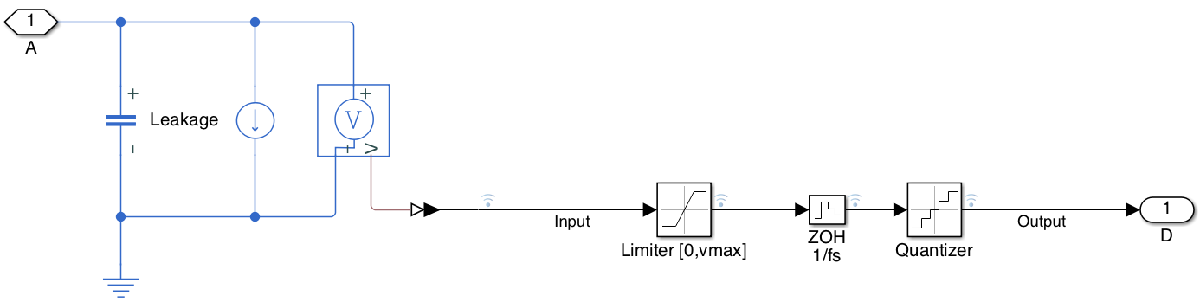

The role of the limiter is to ensure if the signal at the input is smaller than zero or larger than maximum voltage applied to the ADC, the output of the limiter will be saturated to zero or maximum voltage respectively. The sample and hold circuit converts the analog signal into the discrete signal that keeps the same value for the duration of the sampling period.This value is then quantized and converted into digital signal. 

This ADC is used in this circuit to view an input signal through diffrerent processing stages of the ADC and view the results. 

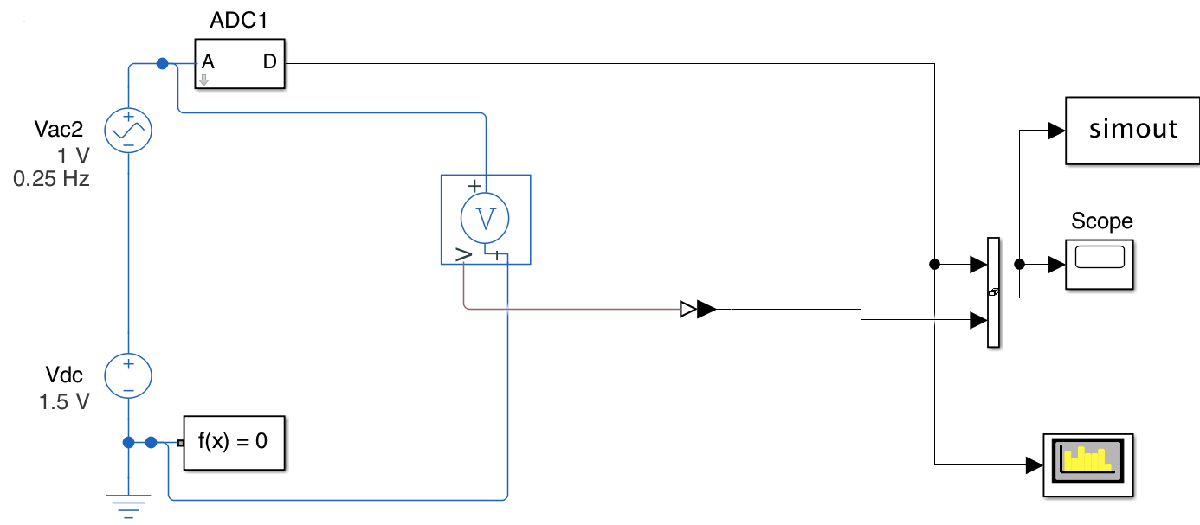

The ADC has the following characteristics: sampling rate$\;f_s =\;12\textrm{Hz}$ , number of bits $N=4$, minimum voltage level $0V$ , maximum voltage level $5V$. 

## Quantization function of A/D converter

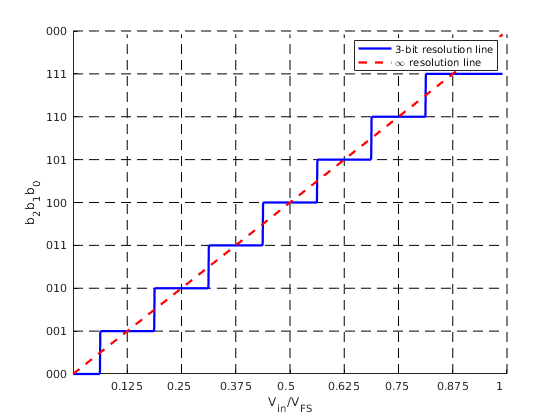

clear all
Vx=0:0.001:0.99;
N=3;
figure, hold on
for i=1:2^N
    x(i)=i/2^N;
    plot(Vx ,i*ones(1,length(Vx)), '--k', 'LineWidth',0.5);
    plot(i*ones(1,length(Vx))/2^N, Vx*2^N, '--k', 'LineWidth',0.5);
end
V_LSB=2^(-N);
Vo=round(Vx/V_LSB);
Vo(Vx>(2^N-1)/2^N)=2^N-1;
a1=plot(Vx, Vo, 'b', 'LineWidth',2);
hold on
a2=plot(Vx,2^N*Vx,'--r', 'LineWidth',2);
legend([a1 a2],["3-bit resolution line" "\infty resolution line"])
xlabel('V_{in}/V_{FS}')
ylabel('b_2b_1b_0')
ylim([0,2^N-0.01])
set(gca,'xtick',x)
set(gca,'xticklabel',x)
set(gca,'yticklabel',dec2bin(get(gca,'ytick'),3))

## Errors during A/D conversion

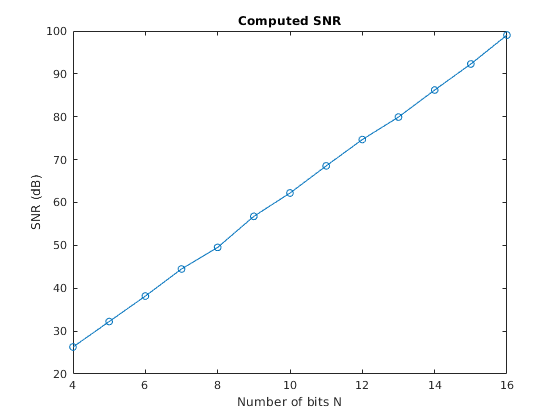

clear all

Fi = 1.1;
Fs = 60;
Nsamples = 1024;
N=16;
x = 0.5+0.5*sin(2*pi*Fi/Fs*(1:Nsamples)); % + 0.001*randn(1,Nsamples);
for n=4:16
    x1=round(x*2^n)/2^n;
    computed_snr(n-3)=snr(x1,Fs);
end
figure
plot(4:16, computed_snr, 'o-')
title('Computed SNR')
xlabel('Number of bits N')
ylabel('SNR (dB)')

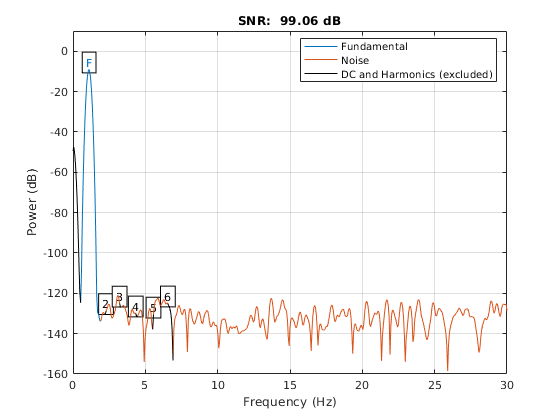

ans = 99.0575

%hold on
%n=4:16
%plot(n, 6.02*n+1.76)

x1=round(x*2^N)/2^N;
snr(x1,Fs)

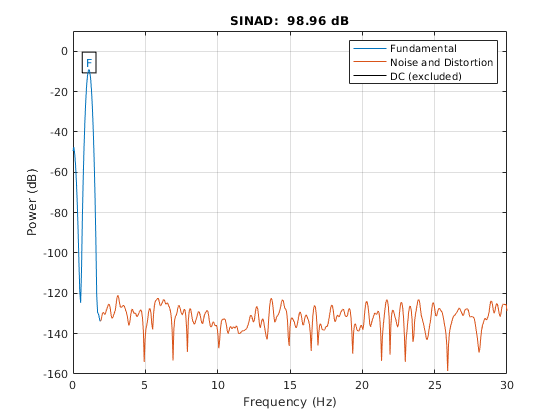

ans = 98.9562

sinad(x1,Fs)

enob=(sinad(x1,Fs)-1.76)/6.02

enob = 16.1456

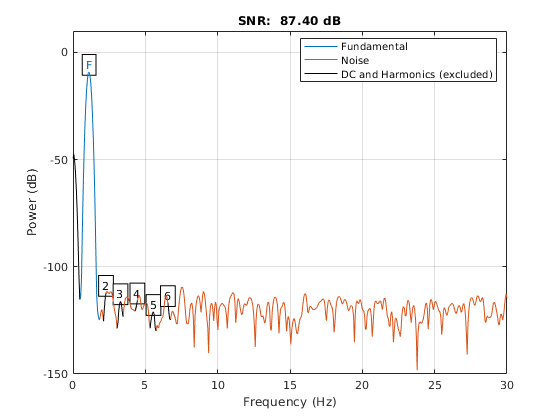

ans = 87.3978


x = 0.5+0.5*sin(2*pi*Fi/Fs*(1:Nsamples)) + randn(1,Nsamples)/2^N;
x1=round(x*2^N)/2^N;
snr(x1,Fs)

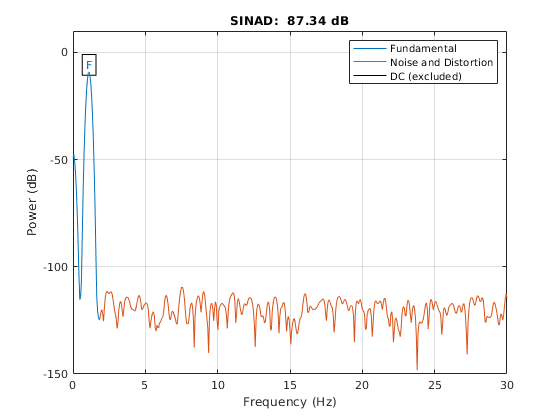

ans = 87.3350

sinad(x1,Fs)

enob=(sinad(x1,Fs)-1.76)/6.02

enob = 14.2151

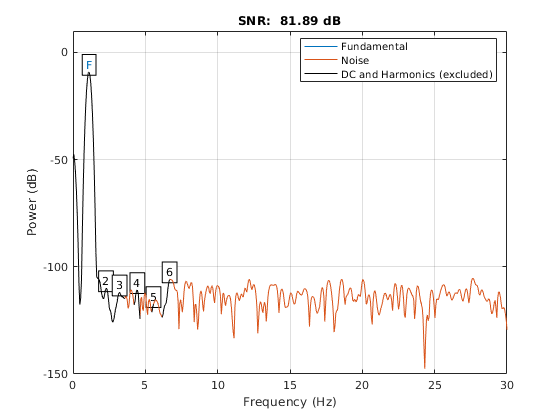

ans = 81.8860


x = 0.5+0.5*sin(2*pi*Fi/Fs*(1:Nsamples)) + randn(1,Nsamples)*2/2^16;
x1=round(x*2^N)/2^N;
snr(x1,Fs)

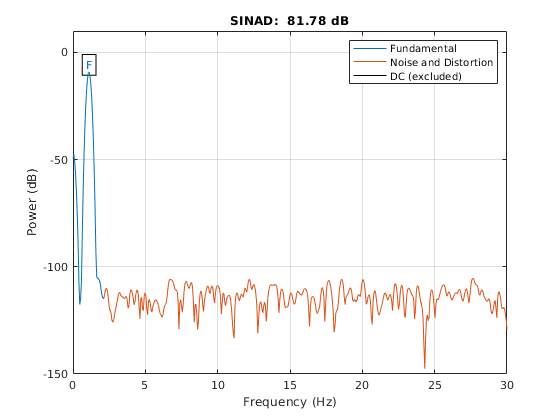

ans = 81.7773

sinad(x1,Fs)

enob=(sinad(x1,Fs)-1.76)/6.02

enob = 13.2919

## Signal Through ADC Processing Stages 

To view the signal through ADC processing stages, the following code is used. 

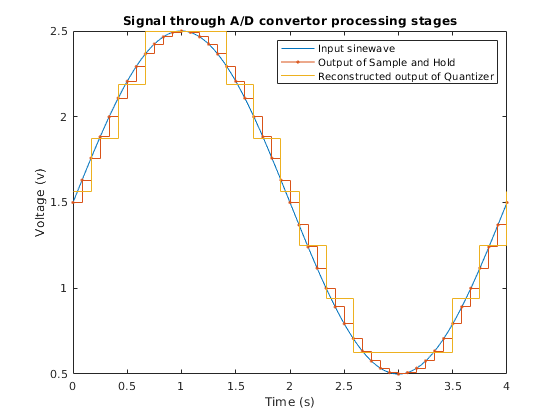

model_name = 'ADCTestSim1';
open_system(model_name);
sim(model_name)

ADCTestOut=load('ADCTest1.mat');
% Vmax=5;
% N=3;
figure
plot(ADCTestOut.data{1}.Values.Time,ADCTestOut.data{1}.Values.Data) % ADC input
hold on, stairs(ADCTestOut.data{3}.Values.Time,ADCTestOut.data{3}.Values.Data, '.-') % signal after S&H circuit
stairs(ADCTestOut.data{2}.Values.Time,ADCTestOut.data{2}.Values.Data) % Signal after quantizer
legend (["Input Sine wave", "Output of Sample and Hold", "Reconstructed output of Quantizer"])
title('Signal through A/D convertor processing stages')
xlabel('Time (s)')
ylabel('Voltage (v)')

legend({'Input sinewave','Output of Sample and Hold','Reconstructed output of Quantizer'})

The input signal shown using blue line is a 0.25 Hz sine wave signal which amplitude is in the range [0.5 V, 2.5 V].Signal at the output of the sample and hold block is shown as a red line. The dots on the red line are the voltage values sampled at the specific time instant. After the signal is sampled, its value is held at the same value for the duration of the sampling period. Quantizer converts the signal after sample and hold circuit into a set of$\;2^N$  values. These values are normally given in binary form. However, here we modeled the output of the A/D converter as reconstructed signal in (E3). (E3).  Of course, with increasing the resolution of A/D converter to, for example, $N=8$ bits, the quantization error would become small and it would be difficult to observe the difference between the output of the sample and hold circuit and the reconstructed output of the quantizer. 